The antiderivative of $e^x$ is, of course, itself. That makes evaluation of $\int_0^1 e^x\,dx$ by the Fundamental Theorem trivial.

format long, I = exp(1)-1

I =    1.718281828459046


MATLAB has a built-in `integral` that estimates the value numerically without finding the antiderivative first. As you can see here, it's often just as accurate. 

integral(@(x) exp(x),0,1)

ans =    1.718281828459045


The numerical approach is far more robust. For example, $e^{\sin x}$ has no useful antiderivative. But numerically it's no more difficult. 

integral(@(x) exp(sin(x)),0,1)

ans =    1.631869608418051


When you look at the graphs of these functions, what's remarkable is that one of these areas is the most basic calculus while the other is almost impenetrable analytically. From a numerical standpoint, they are practically the same problem.

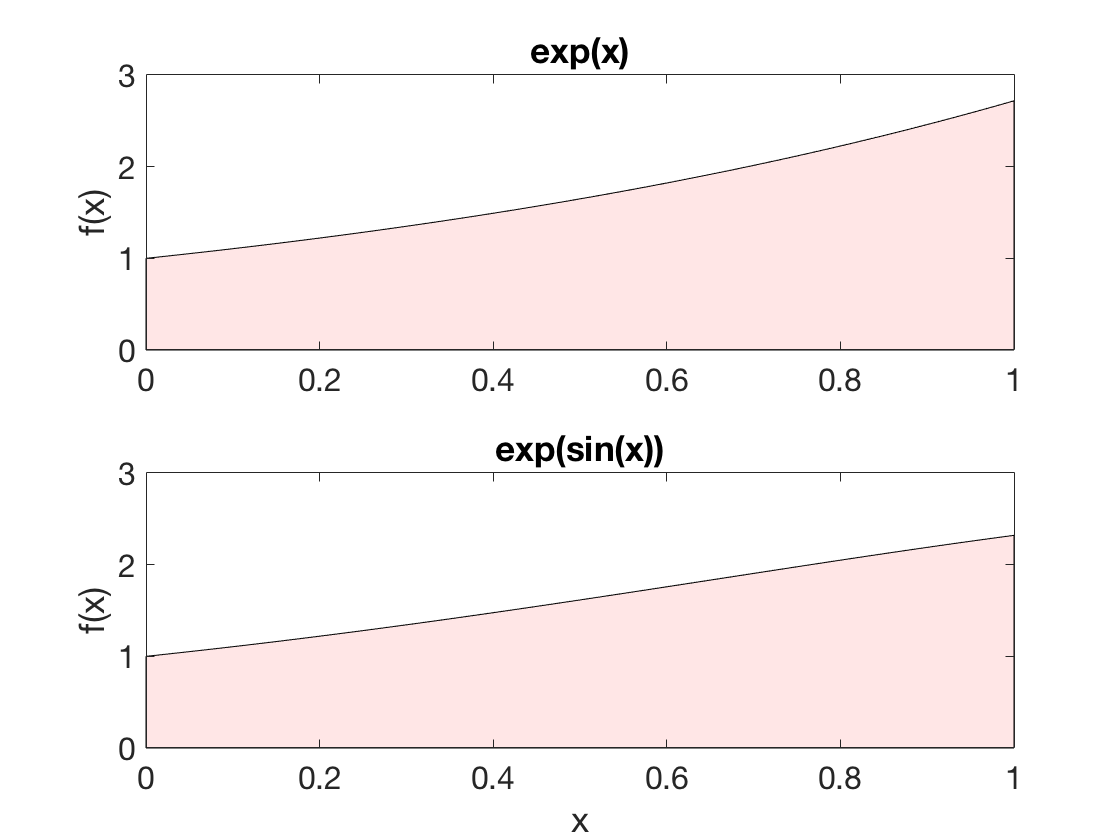

x = linspace(0,1,201)';
subplot(2,1,1), fill([x;1;0],[exp(x);0;0],[1,0.9,0.9])
title('exp(x)')  % ignore this line
ylabel('f(x)')    % ignore this line
subplot(2,1,2), fill([x;1;0],[exp(sin(x));0;0],[1,0.9,0.9])
title('exp(sin(x))')  % ignore this line
xlabel('x'), ylabel('f(x)')    % ignore this line